Trans = struct;
Trans.size = 2; % n elements square
Trans.nElements = Trans.size^2;
Trans.delta = 1e-3; % 1mm spacing
Trans.elementWidth = 0.8e-3;
Trans.width = Trans.delta * (Trans.size-1);

Trans.ids = reshape(1:Trans.nElements,Trans.size,Trans.size);
Trans.lims = Trans.width/2;
Trans.coords = -Trans.lims:Trans.delta:Trans.lims;
Trans.CoordsMatrix(1,:,:) =  repmat(Trans.coords,Trans.size,1);
Trans.CoordsMatrix(2,:,:) =  rot90(repmat(Trans.coords,Trans.size,1));
Trans.CoordsMatrix(3,:,:) = zeros(Trans.size,Trans.size);
Trans.CoordsVector = [  reshape(Trans.CoordsMatrix(1,:,:,:),1,[]);...
                        reshape(Trans.CoordsMatrix(2,:,:,:),1,[]);...
                        reshape(Trans.CoordsMatrix(3,:,:,:),1,[])]';

%imagesc(squeeze(Trans.CoordsMatrix(1,:,:)))
%imagesc(squeeze(Trans.CoordsMatrix(2,:,:)))
%imagesc(Trans.ids)


PD = struct;

for i = 1:3
    PD.delta(i) = (1/100)*1e-3;
    PD.width(i) = Trans.width;
    PD.size(i) = PD.width(i)/PD.delta(i) + 1;
    PD.lims(i) = PD.width(i)/2;
end

%PD.size = PD.size * 1.5;


PD.nElements = prod(PD.size);
PD.ids = reshape(1:PD.nElements,PD.size(1),PD.size(2),PD.size(3));

%PD.displacements = zeros(PD.size(1),PD.size(2),PD.size(3));

for i = 1:3
    PD.coords(i,:) = linspace(-PD.lims(i),PD.lims(i),PD.size(i));
    PD.CoordsMatrix(i,:,:,:) =  repmat(PD.coords(i,:),1,1,PD.size(i),PD.size(i));
end

PD.CoordsMatrix(2,:,:,:) = rot90_3D(squeeze(PD.CoordsMatrix(2,:,:,:)),3,1);
PD.CoordsMatrix(3,:,:,:) = rot90_3D(squeeze(PD.CoordsMatrix(3,:,:,:)),2,1);

PD.CoordsVector = [  reshape(PD.CoordsMatrix(1,:,:,:),1,[]);...
                     reshape(PD.CoordsMatrix(2,:,:,:),1,[]);...
                     reshape(PD.CoordsMatrix(3,:,:,:),1,[])     ]';

px2el_dists = zeros(Trans.nElements,PD.nElements);
PD.disp = zeros(PD.size);

for px = 1:PD.nElements
    for el = 1:Trans.nElements
        px2el_dists(el,px) = distance(Trans.CoordsVector(el,:),PD.CoordsVector(px,:));    
    end
end


Hz = 3e6;
w = Hz * 2* pi;
c = 1540;
wavelength = c/Hz;
k = 2*pi/wavelength;
A = 1;
t = 0;
T=1/Hz;

pixel_counter = 0;

%dispstat('','init')
for x = 1:PD.size(1)
    for y = 1:PD.size(2)
        for z = 1:PD.size(2)
            px = PD.ids(x,y,z);
            for el = 1:Trans.nElements
                r = px2el_dists(el,px);
                PD.disp(x,y,z) = PD.disp(x,y,z) + abs(wave_disp(A,r,k,w,t));
            end
            %pixel_counter = pixel_counter + 1;
            %dispstat(append('Progress:',num2str(pixel_counter*100/PD.nElements),'%'))
        end
    end
end
disp(PD.size)

   101   101   101



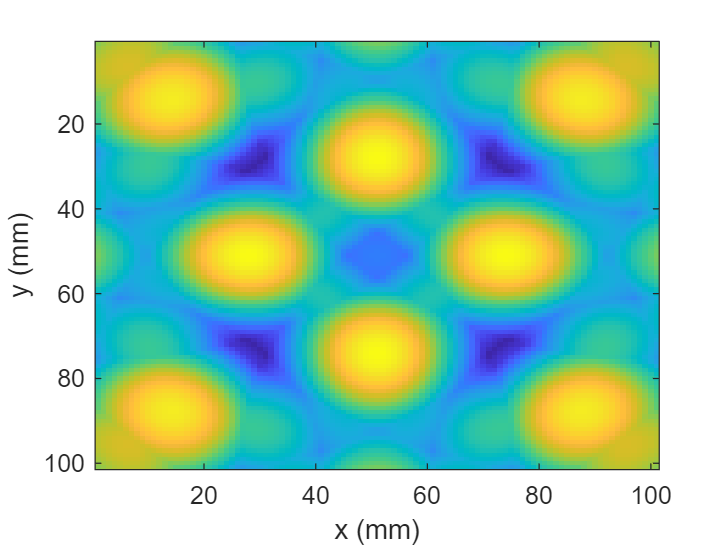

imagesc(squeeze(PD.disp(:,:,1)))
xlabel('x (mm)')
ylabel('y (mm)')

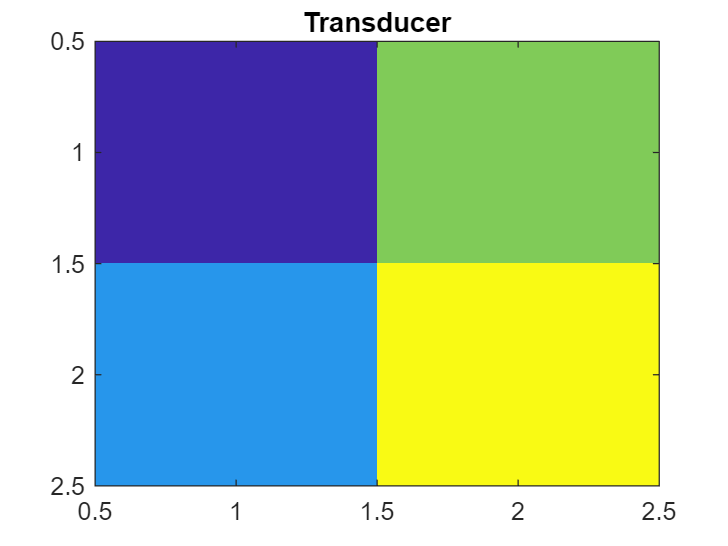


imagesc(Trans.ids)
title('Transducer')

function displacement = wave_disp(A,r,k,w,t)
displacement = real((A./r) .* exp(1i.*(k.*r - w.*t)));
end

function r = distance(r1,r2)
rx = r1(1) - r2(1);
ry = r1(2) - r2(2);
rz = r1(3) - r2(3);

r = sqrt(rx^2 + ry^2 + rz^2);
end
